# Ler os dados

clear; clc; close all;

serie = load('serie_tempo_cn.dat');
data = load('crank_nicolson.dat');        

tempo = serie(:, 1);
T_centro = serie(:, 2);
T_max = serie(:, 3);

# Reconstruir malha

x = data(:,1);
y = data(:,2);
T = data(:,3);

Nx = length(unique(x));
Ny = length(unique(y));

X = reshape(x, Ny, Nx)';  
Y = reshape(y, Ny, Nx)';
Temp = reshape(T, Ny, Nx)';

# Inércia Térmica (Série Temporal)

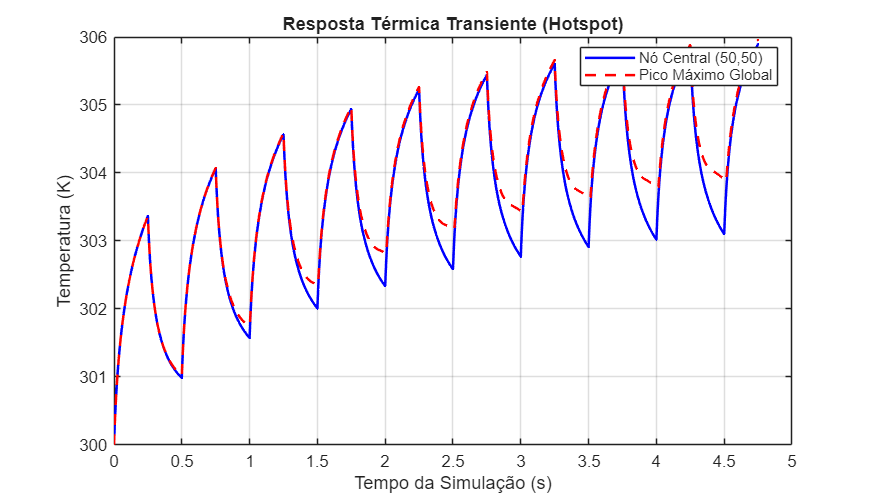

figure('Name', '1. Transiente Térmico', 'Position', [100, 100, 700, 400]);
plot(tempo, T_centro, 'b-', 'LineWidth', 1.5); hold on;
plot(tempo, T_max, 'r--', 'LineWidth', 1.5);
title('Resposta Térmica Transiente (Hotspot)');
xlabel('Tempo da Simulação (s)');
ylabel('Temperatura (K)');
legend('Nó Central (50,50)', 'Pico Máximo Global', 'Location', 'best');
grid on;

# Superfície 3D

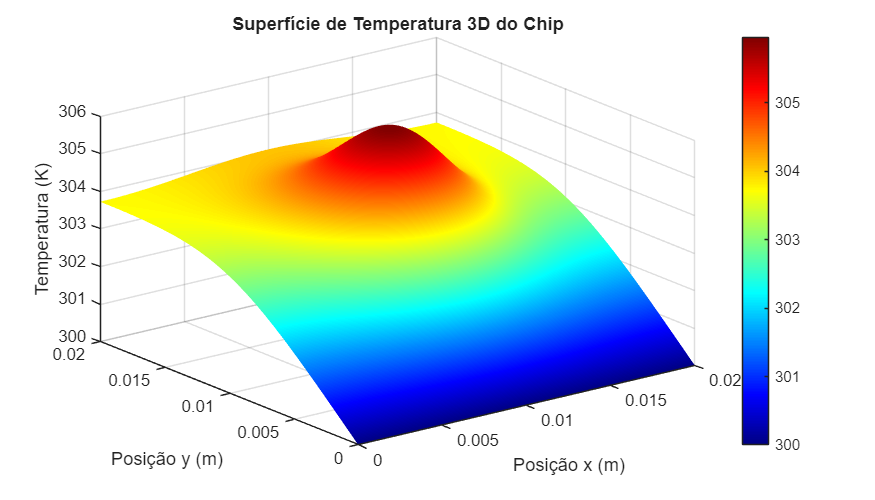

figure('Name', '2. Superfície 3D', 'Position', [150, 150, 700, 400]);
surf(X, Y, Temp);
shading interp;
colormap(jet); 
colorbar;
xlabel('Posição x (m)');
ylabel('Posição y (m)');
zlabel('Temperatura (K)');
title('Superfície de Temperatura 3D do Chip');

# Gráfico de Perfil

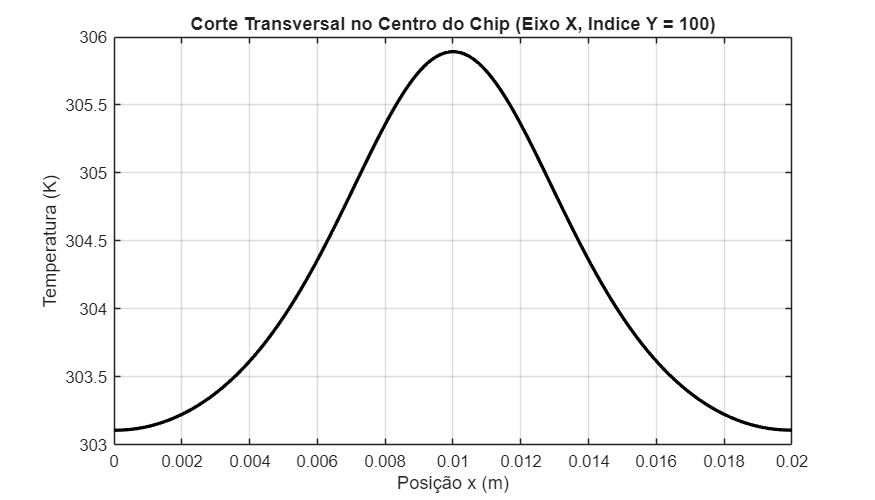

meio_x = round(Nx / 2);
meio_y = round(Ny / 2);

figure('Name', '3. Perfil Transversal (Eixo X)', 'Position', [200, 200, 700, 400]);
plot(X(:, meio_y), Temp(:, meio_y), 'k-', 'LineWidth', 2);
xlabel('Posição x (m)');
ylabel('Temperatura (K)');
title(sprintf('Corte Transversal no Centro do Chip (Eixo X, Indice Y = %d)', meio_y));
grid on;

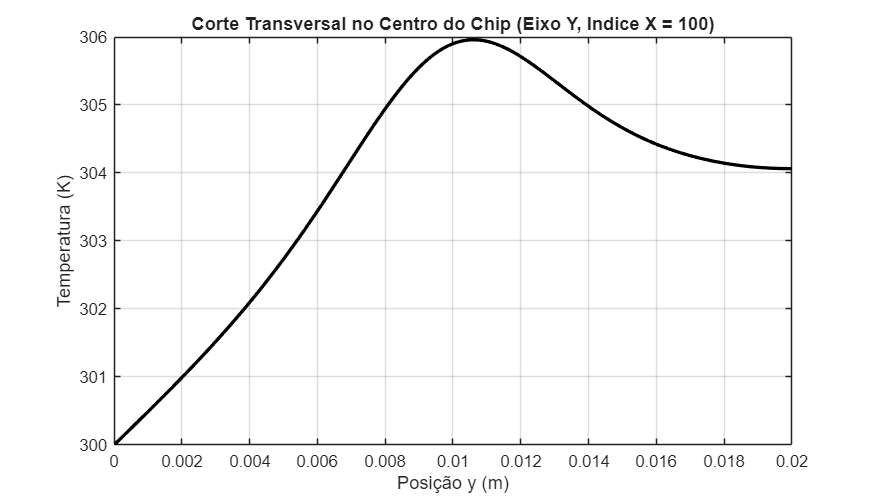



figure('Name', '3. Perfil Transversal (Eixo Y)', 'Position', [250, 250, 700, 400]);
plot(Y(meio_x, :), Temp(meio_x, :), 'k-', 'LineWidth', 2);
xlabel('Posição y (m)');
ylabel('Temperatura (K)');
title(sprintf('Corte Transversal no Centro do Chip (Eixo Y, Indice X = %d)', meio_x));
grid on;

# Mapa de Calor

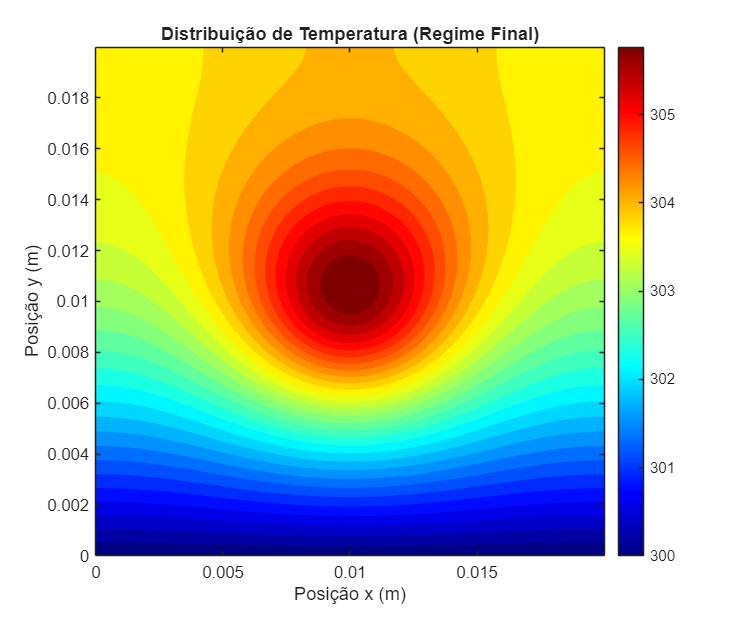

figure('Name', '4. Mapa de Calor (Top-Down)', 'Position', [250, 250, 600, 500]);
contourf(X, Y, Temp, 30, 'LineColor', 'none');
colormap(jet);
colorbar;
xlabel('Posição x (m)');
ylabel('Posição y (m)');
title('Distribuição de Temperatura (Regime Final)');
axis equal; tightval = axis; axis(tightval);

# Estudo de Convergência

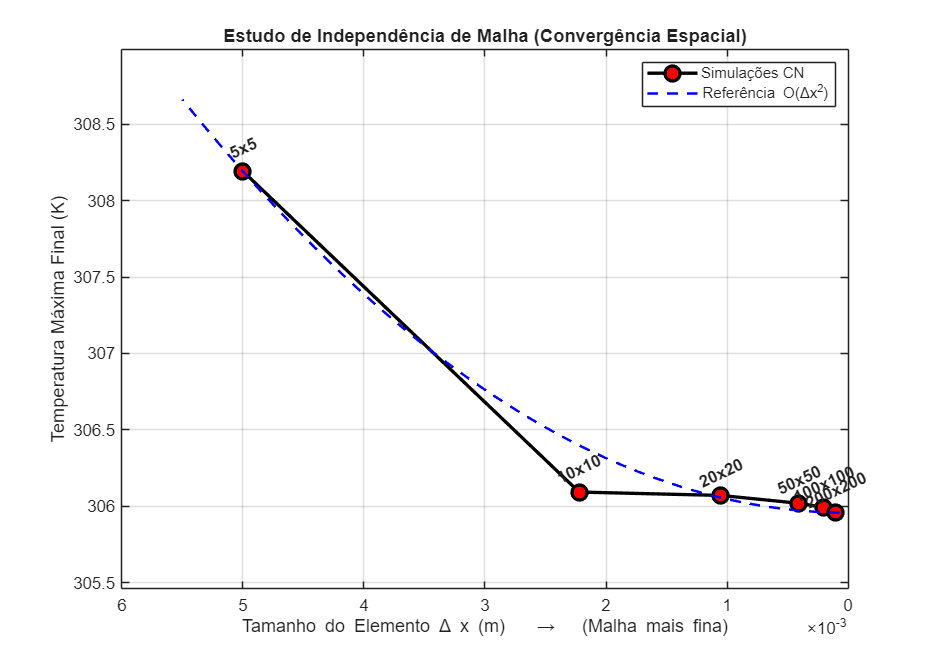

dados_conv = load('dados_convergencia.dat');

N_nos_bruto  = dados_conv(:, 1);
dx_bruto     = dados_conv(:, 2);
T_max_bruto  = dados_conv(:, 3);

[N_nos, indices] = sort(N_nos_bruto);
dx_valores       = dx_bruto(indices);
T_max_resultados = T_max_bruto(indices);

figure('Name', '7. Convergencia Espacial', 'Position', [150, 150, 750, 530]);

plot(dx_valores, T_max_resultados, '-ko', ...
    'LineWidth', 2, 'MarkerSize', 9, 'MarkerFaceColor', 'r', ...
    'DisplayName', 'Simulações CN');
hold on;

dx_ref = linspace(min(dx_valores) * 0.7, max(dx_valores) * 1.1, 200);
C      = T_max_resultados(end);
escala = (T_max_resultados(1) - T_max_resultados(end)) / ...
         (max(dx_valores)^2 - min(dx_valores)^2);
T_ref  = C + escala * (dx_ref.^2 - min(dx_valores)^2);
plot(dx_ref, T_ref, 'b--', 'LineWidth', 1.5, 'DisplayName', 'Referência O(\Deltax^2)');

set(gca, 'XDir', 'reverse');
ylim([min(T_max_resultados) - 0.5, max(T_max_resultados) + 0.8]);

title('Estudo de Independência de Malha (Convergência Espacial)');
xlabel('Tamanho do Elemento \Delta x (m)   \rightarrow   (Malha mais fina)');
ylabel('Temperatura Máxima Final (K)');
legend('Location', 'northeast');
grid on;

for i = 1:length(N_nos)
    texto = sprintf('%dx%d', N_nos(i), N_nos(i));
    text(dx_valores(i), T_max_resultados(i) + 0.15, texto, ...
        'HorizontalAlignment', 'center', ...
        'Rotation', 25, ...
        'FontSize', 10, ...
        'FontWeight', 'bold');
end